## 24-774: Lab 1

Due Sept 20

## Team: 4

Pranav Narahari

Keitaro Nishimura

Emma Benjaminson

## Notes on Plant Model and Reference: 

Yaw should have amplitude $\pi$/4 rad (0.7854) and freq 0.5 rad/s (0.08 Hz, T = 12.5s)

Pitch should have amplitude $\pi$/6 rad (0.5236)and freq 0.4 rad/s (0.06 Hz, T = 16.7s)

## Preliminaries

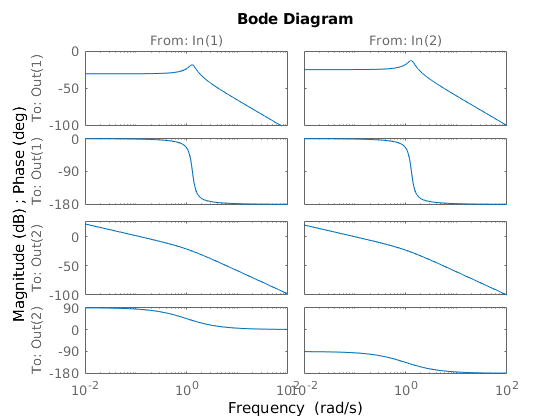

quanser_aero_parameters
quanser_aero_state_space

% nominal plant model 
Gnom = ss(A, B, C, D) ; 
bode(Gnom) ; 

% bodemag(Gnom) ;

The outputs to channel 1 both show typical second order behavior with a resonant peak at about 1.3 rad/s. The output to channel 2 seems to be a proper system with a pole and zero, with first order characteristics. I cannot see anything that I would call "unusual". But I thought that the Bode plots on the diagonals (1,1) and (2,2) would be more similar and the off-diagonal plots would be more chaotic? Why are all the bodes for a particular output (regardless of the input) very similar? --> Maybe its related to coupling somehow?

--> control dominant - one input is stronger than the other

**WHAT ARE CHANNELS 1 AND 2 ON INPUT AND OUTPUT REPRESENTING?**

% saturation nonlinearity to limit control voltages to +/- 25V
Wu = eye(2)*1/25 ; 


## PID Control

See the Lab1_NomPlantModel.slx and Lab1_PIDControllers.slx files for PID controller implementation. 

## Dynamic Decoupling

$G_s = G_D G_M^{-1} G$ where $G_M$ is the plant model (Gnom above). $G_D$ is the diagonal portion of the plant model. $G_M^{-1}$ is a proper, stable approximation of the inverse of the nominal plant model.  (I think the last G in the expression is $G_M$ --> this is correct for the simulation. On the hardware we replace G with the actual plant.) 

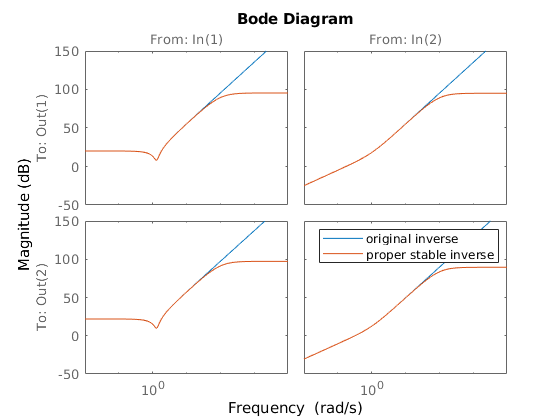

s = tf('s') ; 
Gm = Gnom ; % plant model
Gd = [Gnom(1,1), 0 ; 0 , Gnom(2,2)]; % diagonal portion of plant model

K = 1E2 ; % position of high frequency poles for making inverse a proper tf
Gm_inv = tf(inv(Gnom))*(1/((s/K)+1))^2 ; % writing the extra poles this way ensures they don't affect the DC gain
% Gm_inv = inv(Gnom)*((K/(s+K))^2) ; % proper, stable inverse of plant model

bodemag(inv(Gnom),Gm_inv) ; legend('original inverse', 'proper stable inverse') ; 

Gd = minreal(Gd) ; 

4 states removed.


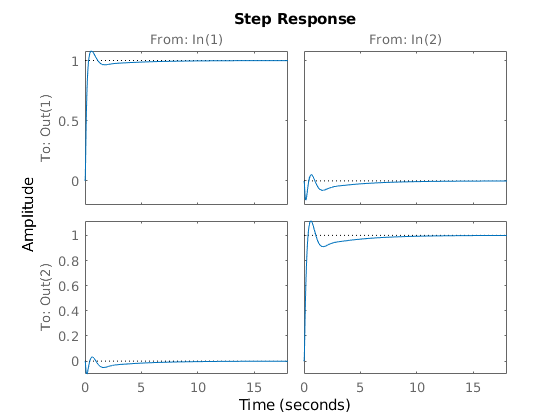

Gm_inv = minreal(Gm_inv) ; 
Gs = tf(Gm_inv)*tf(Gd) ; 
Gs = minreal(Gs,1e-3) ; 

%% converting decoupling controller to discrete time

% PID for yaw
% Kp_y = 700; 
% Ki_y = 20; 
% Kd_y = 600; 
Kp_y = 150; 
Ki_y = 0; 
Kd_y = 80; 
N_y = 100; 
Kyaw = Kp_y + Ki_y*(1/s) + Kd_y*(N_y / (1 + N_y*(1/s))) ; 

% PID for pitch
% Kp_p = 700; 
% Ki_p = 10; 
% Kd_p = 400; 
Kp_p = 200; 
Ki_p = 60; 
Kd_p = 80; 
N_p = 100; 
Kpitch = Kp_p + Ki_p*(1/s) + Kd_p*(N_y / (1 + N_y*(1/s))) ; 
Kpid = [Kpitch, 0 ; 0, Kyaw] ; 
Kdecoupling = Gs*Kpid ; 
Kdecoupling = minreal(Kdecoupling);

% put into controllable canonical form
% Kdecoupling_canon = canon(Kdecoupling,'modal') ; % is companion a good mode to use? 

% sampling time
Ts = 1/500 ; % assuming 500Hz sampling rate
step(feedback(Kdecoupling*Gnom,eye(2))) 

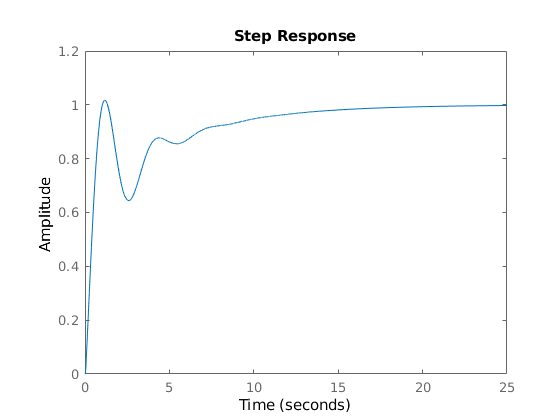

kDT2 = c2d(Kdecoupling,Ts,'zoh') ; 
step(feedback(kDT2(1,1)*c2d(Gnom(1,1),Ts),1))

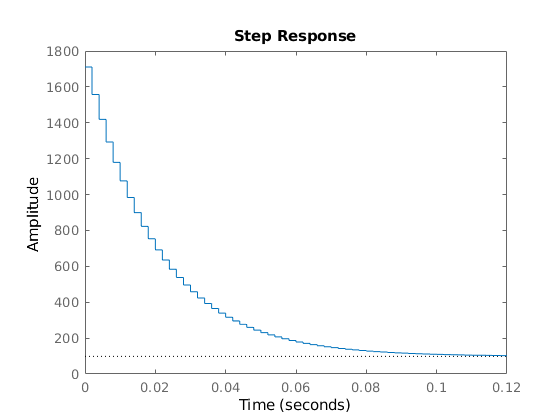


 K_lqr = [(1711*s + 4910)/(s+50), (-1557*s - 5153)/(s+50) ; 
         (2432*s + 7817)/(s+50), (921.5*s + 3308)/(s+50) ] ; 
 kDT = c2d(K_lqr,Ts,'zoh') ; 
 step(kDT(1,1)) 

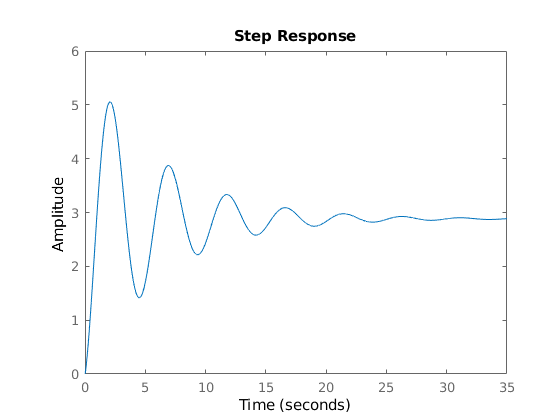

 step(kDT(1,1)*c2d(Gnom(1,1),Ts))


% B0 = 0 FIX THIS
%tf(minreal(kDT))
%kDT_min = balred(kDT,6)
%bode(kDT,kDT_min)
%ss(ans);


%kDT = canon(minreal(kDT),'companion') % companion results in singular controllability matrix; neither has an effect on tf?
%kDT_tf = ss2tf(kDT.A,kDT.B,kDT.C,kDT.D,1) % what is the numerator, denominator?

The controller output is now very small compared to the reference signals. Why is that happening? Does it have to do with the location of the poles I added to make the inverse plant proper?

See Lab1_DynamicDecoupledPlantModel.slx and Lab1_DynamicDecoupledControllers.slx for this implementation.

## State Space Control

% KF
Q_kf = 1*eye(4) ; 
R_kf = 1*eye(2) ; 

% LQR
Q = 1 * eye(4) ; 
R = 1 * eye(2) ; 
[Klqr,~,~] = lqr(Gnom,Q,R) ; 